I didn't put in a data load section because I wasn't sure what the path would be, so just double click on mtSpikeTimes.mat and retinaData.mat to manually load in the data

## 1.1 Raster Plots

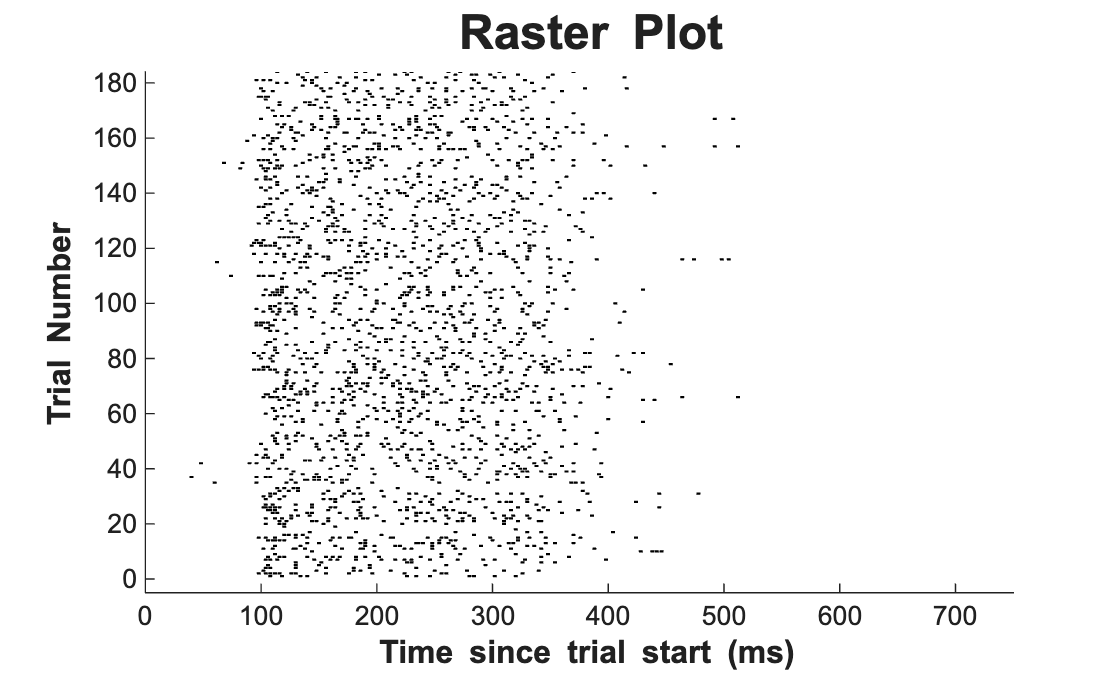

figure;
hold on

num_trials = length(mtSpikeTimes);

spike_height = 0.8; 

for trial = 1:num_trials
    if ~isempty(mtSpikeTimes{trial})
        spike_times = mtSpikeTimes{trial} * 1000; % convert to ms

        for s = 1:length(spike_times)
            x = spike_times(s);
            line([x x], ...
                 [trial - spike_height/2, trial + spike_height/2], ...
                 'Color', 'k', 'LineWidth', 1.5);
        end
    end
end

set(gca, 'FontName', 'Arial');
title('\bf Raster Plot', 'FontSize', 18)

ylabel('\bf Trial Number', 'FontSize', 12)
xlabel('\bf Time since trial start (ms)', 'FontSize', 12)

ylim([-5, num_trials])
xlim([0, 750])

box off

## 1.2 Peri-Stimulus Time Histograms

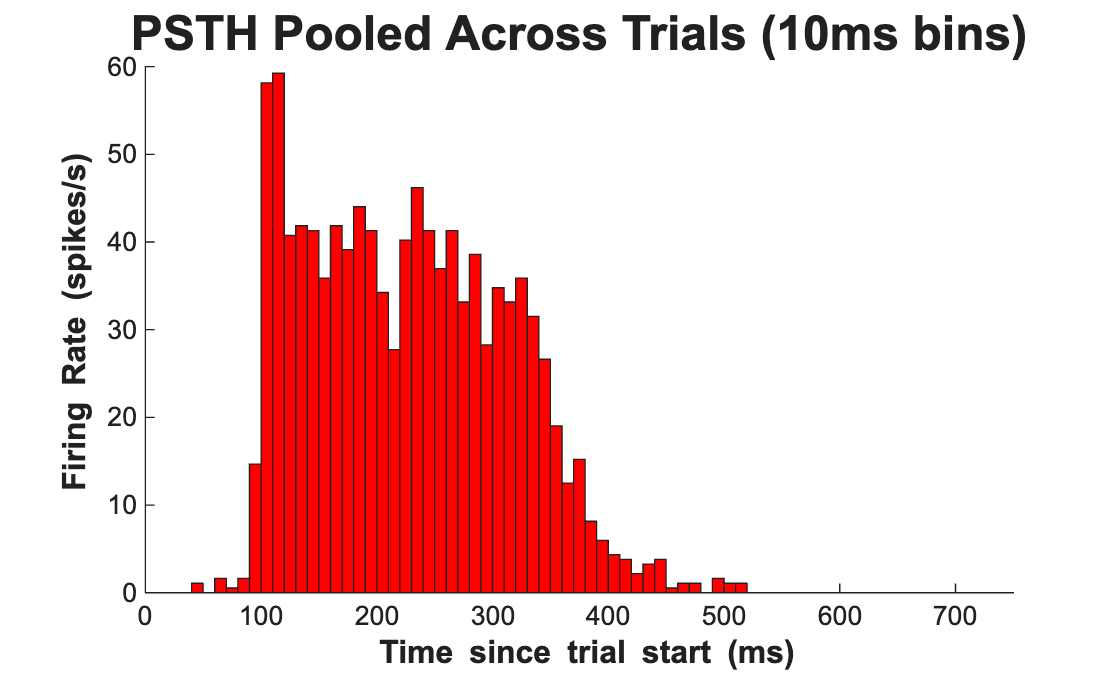

% Part A
function func = psth(data, bin_size)
    bins = 0:bin_size:750;
    all_spike_times = [data{:}]; % gets all trials concatenated
    all_spike_times = all_spike_times * 1000;
    spike_counts = histcounts(all_spike_times, bins);
    num_trials = length(data);
    firingRate = spike_counts / ((bin_size / 1000) * num_trials);
    figure;
    b = bar(bins(1:end-1), firingRate, 'histc');
    b.FaceColor = 'red';
    
    set(gca, 'FontName', 'Arial');
    xlim([0, 750])
    title(sprintf('PSTH Pooled Across Trials (%dms bins)', bin_size), 'FontSize', 18)
    ylabel('\bf Firing Rate (spikes/s)', 'FontSize', 12)
    xlabel('\bf Time since trial start (ms)', 'FontSize', 12)

    box off
end

psth(mtSpikeTimes, 10);

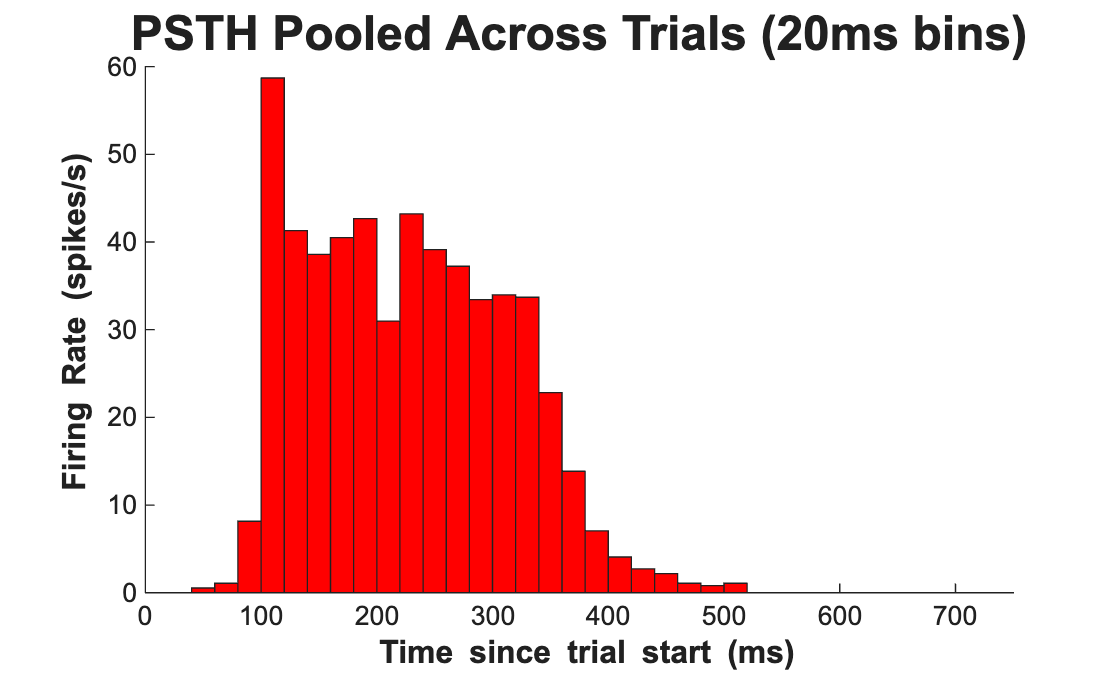

psth(mtSpikeTimes, 20);

With the 10ms bin size, the data looks less smooth when compared to the 20ms bin plot. The 10ms bin plot also has better temporal resolution than the 20ms bin plot. 

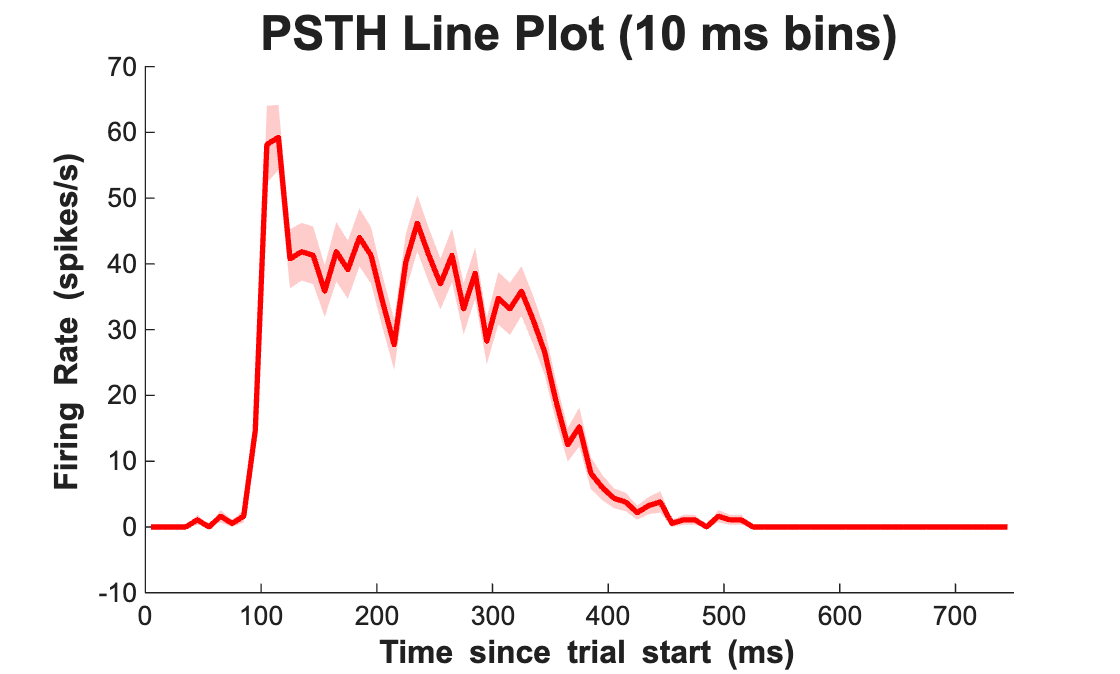

% Part B
function psth_line(data, bin_size)

    bins = 0:bin_size:750;
    num_trials = length(data);
    num_bins = length(bins) - 1;
    trial_rates = zeros(num_trials, num_bins);

    for i = 1:num_trials
        spike_times = data{i} * 1000; % convert to ms
        spike_counts = histcounts(spike_times, bins);
        trial_rates(i, :) = spike_counts / (bin_size / 1000);
    end

    mean_rate = mean(trial_rates, 1);
    sem_rate = std(trial_rates, 0, 1) / sqrt(num_trials);
    bin_centers = bins(1:end-1) + bin_size/2;

    figure;
    hold on;

    fill([bin_centers fliplr(bin_centers)], ...
         [mean_rate + sem_rate, fliplr(mean_rate - sem_rate)], ...
         'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
    plot(bin_centers, mean_rate, 'r', 'LineWidth', 2);

    title(sprintf('PSTH Line Plot (%d ms bins)', bin_size), 'FontSize', 18)
    xlabel('Time since trial start (ms)')
    ylabel('Firing Rate (spikes/s)')

    set(gca, 'FontName', 'Arial');    
    ylabel('\bf Firing Rate (spikes/s)', 'FontSize', 12)
    xlabel('\bf Time since trial start (ms)', 'FontSize', 12)
    xlim([0, 750])
    box off
end
psth_line(mtSpikeTimes, 10);

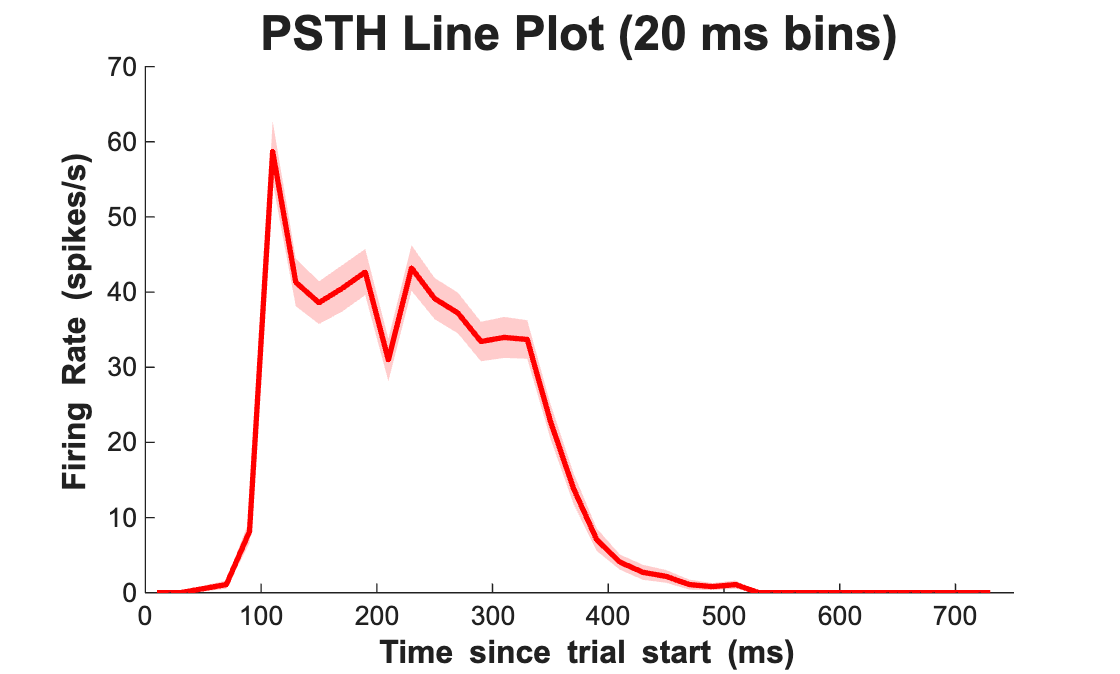

psth_line(mtSpikeTimes, 20);

## 2.1 Basic Spike Train Statistics

% Part A
num_trials = length(mtSpikeTimes);
count_30 = zeros(num_trials, 1);

for i = 1:num_trials
    spike_times = mtSpikeTimes{i} * 1000; % convert to ms
    if isempty(spike_times)
        continue;
    end
    first_spike = spike_times(1);
    spikes_after = spike_times(spike_times > first_spike);
    count_30(i) = sum(spikes_after <= first_spike + 30);
end
firing_rate_30 = count_30/0.03;
avg_firing_rate_30 = mean(firing_rate_30);
fprintf('Average firing rate (30-ms window): %d \n', avg_firing_rate_30);

Average firing rate (30-ms window): 4.855072e+01 


% Part B
fano_factor_30 = var(count_30) / mean(count_30);
fprintf('Fano factor (30-ms window): %d \n', fano_factor_30);

Fano factor (30-ms window): 9.741457e-01 



% Part C
count_300 = zeros(num_trials, 1);

for i = 1:num_trials
    spike_times = mtSpikeTimes{i} * 1000; % convert to ms
    if isempty(spike_times)
        continue;
    end
    first_spike = spike_times(1);
    spikes_after = spike_times(spike_times > first_spike);
    count_300(i) = sum(spikes_after <= first_spike + 300);
end
firing_rate_300 = count_300/0.3;
avg_firing_rate_300 = mean(firing_rate_300);

fprintf('Average firing rate (300-ms window): %d \n', avg_firing_rate_300);

Average firing rate (300-ms window): 3.190217e+01 


fano_factor_300 = var(count_300) / mean(count_300);
fprintf('Fano factor (300-ms window): %d \n', fano_factor_300);

Fano factor (300-ms window): 2.234222e+00 


In the 30ms window, the Fano factor is close to 1. This indicates that the spike count variability in this window is close to the one created by the Poisson process. In the 300ms window, the Fano factor increases above 1. This indicates that the spike count variability is greater than what we would have expected from the Poisson process. This could imply that in larger time windows, there is greater variance which would increase the Fano factor. 

## 2.2 Interspike Intervals

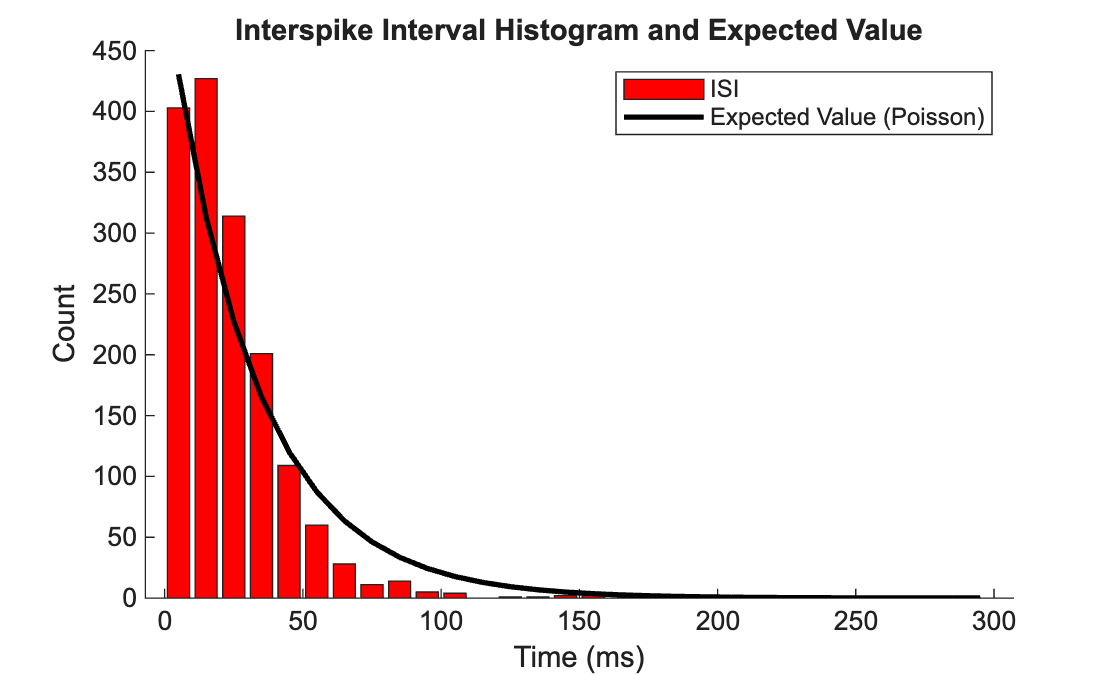

all_isi = [];

for i = 1:length(mtSpikeTimes)
    spike_times = mtSpikeTimes{i} * 1000; % ms
    if isempty(spike_times)
        continue;
    end
    first_spike = spike_times(1);
    spike_range = spike_times(spike_times > first_spike & spike_times <= first_spike + 300);

    if length(spike_range) > 1
        isi = diff(spike_range);
        all_isi = [all_isi, isi];
    end
end

figure;
hold on;
bins = 0:10:300;
counts = histcounts(all_isi, bins);
bin_centers = bins(1:end-1) + diff(bins)/2;
bar(bin_centers, counts, 'FaceColor', 'red');

% Possion calculations
lambda = avg_firing_rate_300;
t = bin_centers / 1000; % convert from ms to seconds
pdf = lambda * exp(-lambda * t);

bin_width = 10 / 1000; % 10ms bins like we did above
expected_vals = pdf * length(all_isi) * bin_width;
plot(bin_centers, expected_vals, 'k', 'LineWidth', 2);

set(gca, 'FontName', 'Arial');    
xlabel('Time (ms)');
ylabel('Count');
title('Interspike Interval Histogram and Expected Value');

legend('ISI', 'Expected Value (Poisson)');
box off;

The ISI and the expected value curve from the Poisson process both have an exponential decay shape. From 60-100ms, the curve does not match the ISI histogram and there are less ISIs than the expected value curve predicts. This is likely due to a refractory period after firing which prevents the neuron from firing again at the rate predicted by the Poisson process calculation. From 10-30ms, the curve also does not match the ISI histogram. There are more ISIs than the expected value curve predicts. This could be because the neuron preferentially fires at a certain rate or whatever stimulus appeared at this 10-30ms range that the Poisson proces did not predict. 

## 3.1 Spike Triggered Average

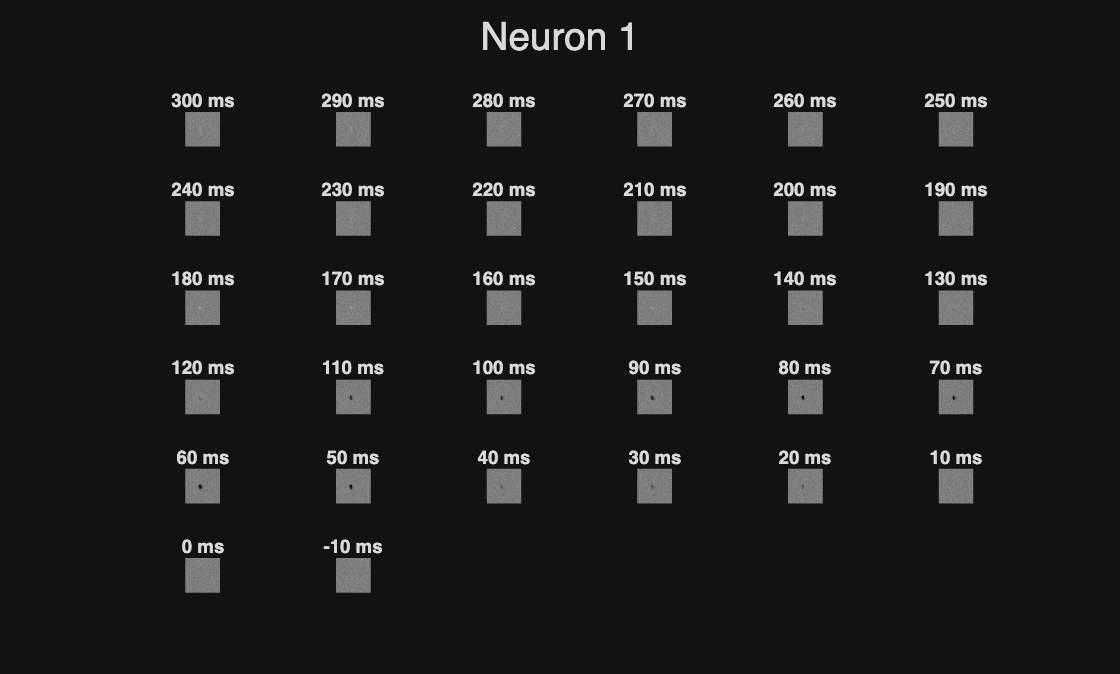

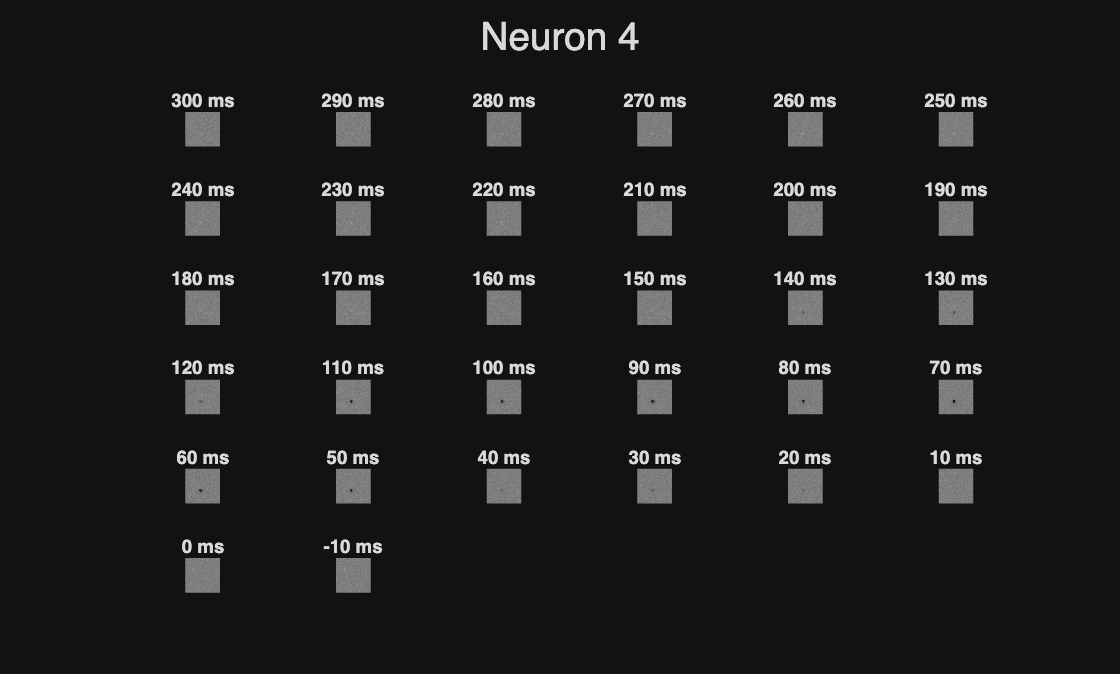

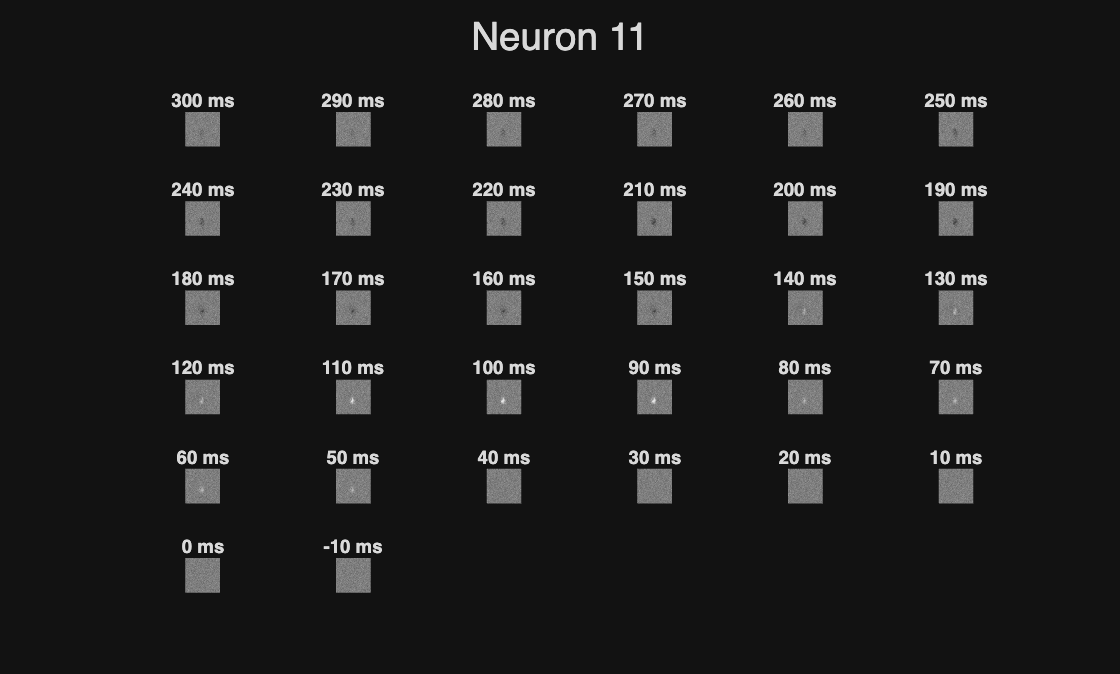

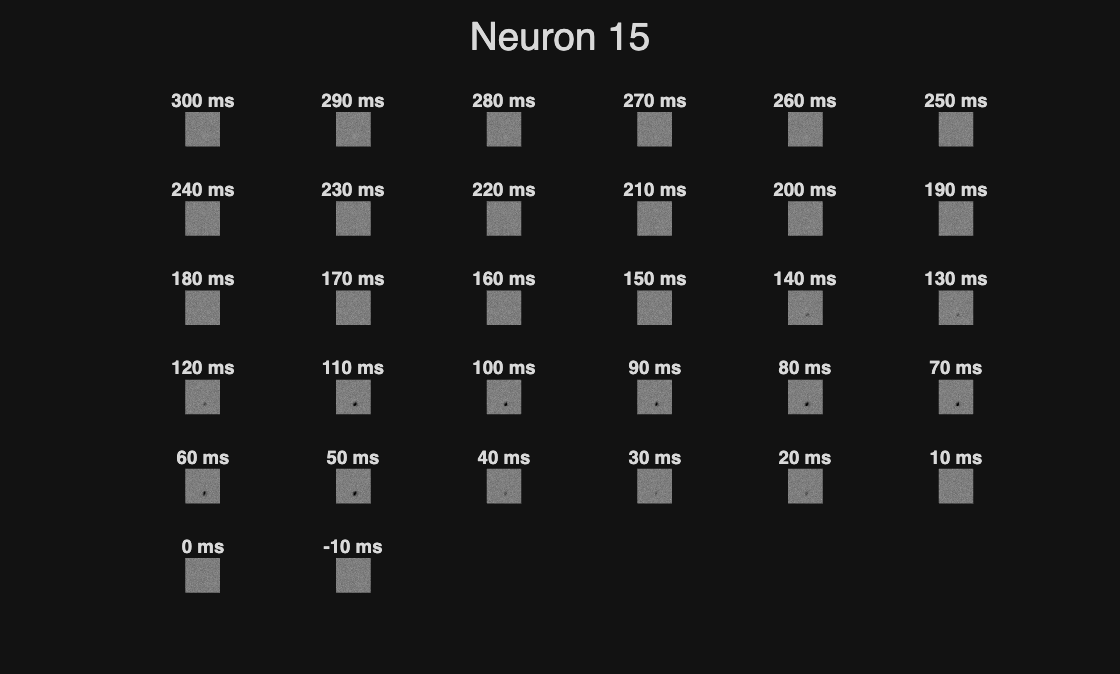

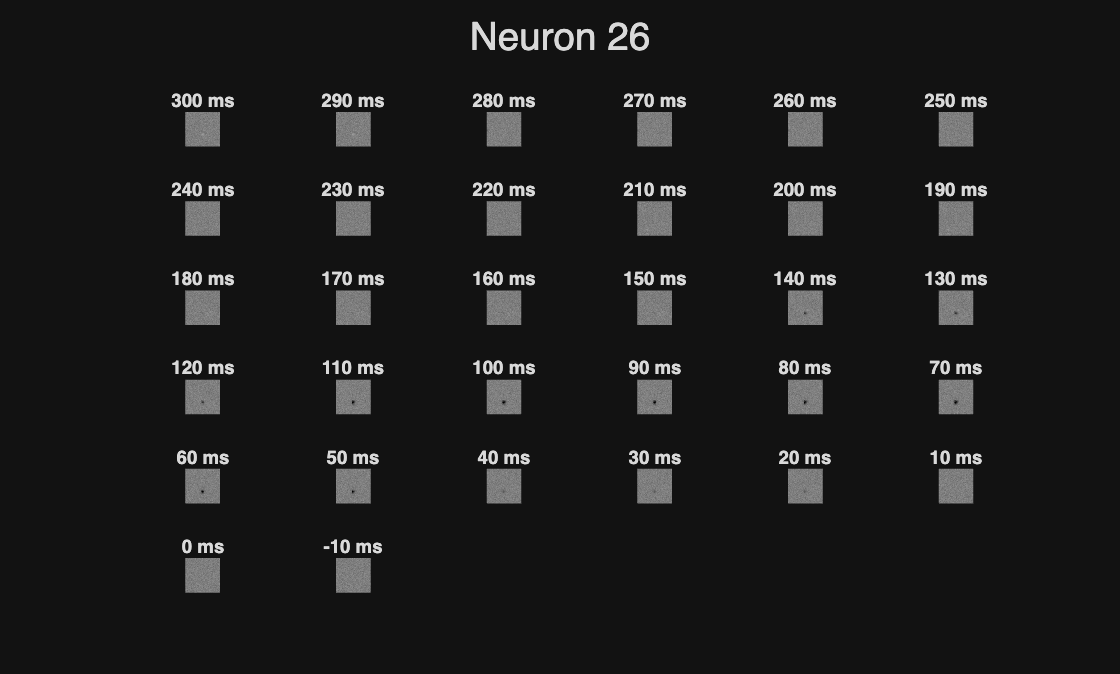

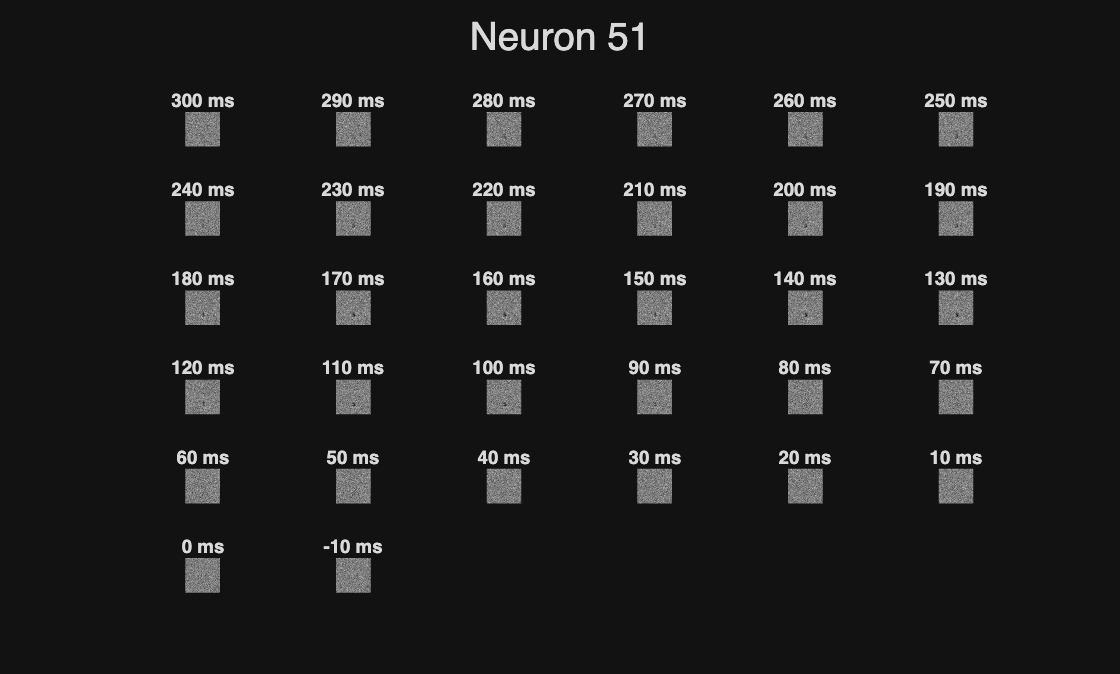

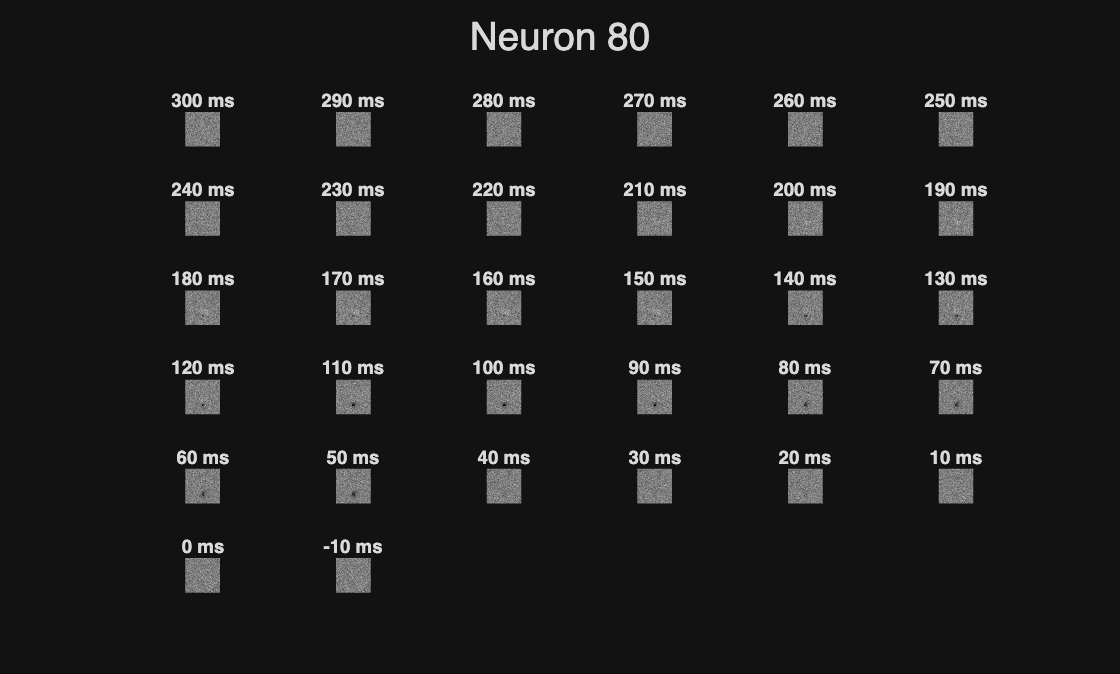

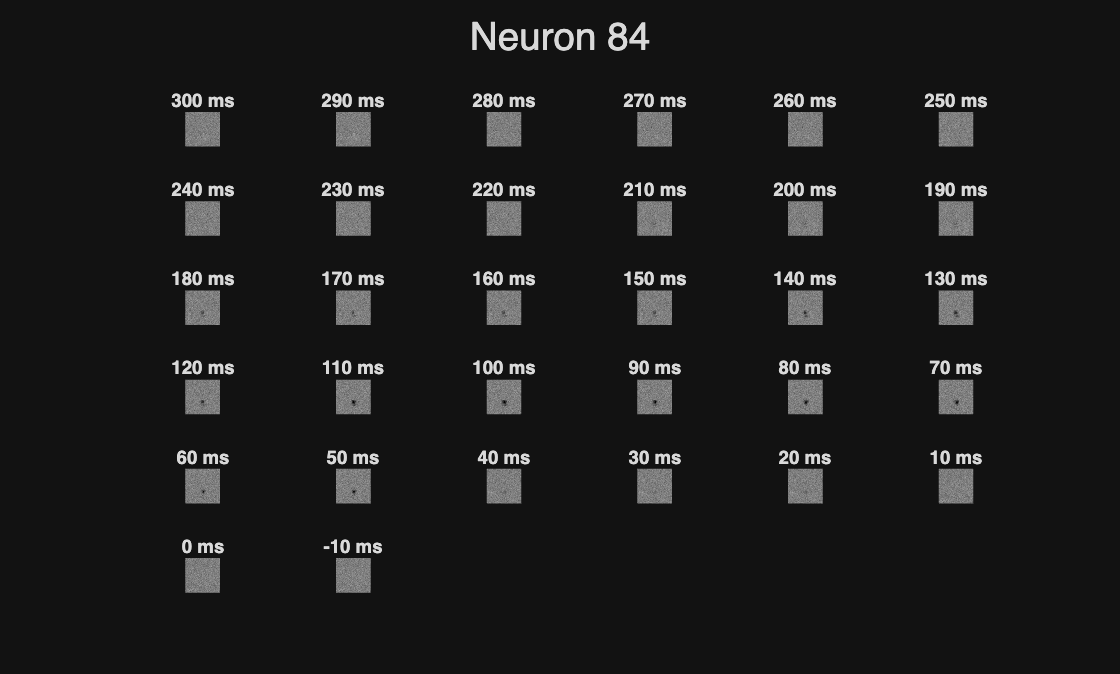

% Part A
function strf = plot_strf(retinaData, neuron)
    % data cleaning, get rid of all that have 0 like problem set says to do
    valid = retinaData.stimulusFrameTimes ~= 0;
    stimulusFrameTimes = retinaData.stimulusFrameTimes(valid);
    stimulus = retinaData.stimulusFrames(:,:,valid) - 0.5;
    stimulus = double(stimulus);
    stimulusTimes = stimulusFrameTimes * 0.1; % convert to ms
    stimulusTimes = double(stimulusTimes);
    spikeTimes = retinaData.spikes{neuron} * 0.1;
    spikeTimes = double(spikeTimes);
    
    lag_times = 300:-10:-10;
    numLags = length(lag_times);
    numSpikes = length(spikeTimes);
    
    stimulus_reshaped = reshape(stimulus, 1600, []);
    spike_idx = round(interp1(stimulusTimes, ...
        1:length(stimulusTimes), ...
        spikeTimes, ...
        'nearest', ...
        'extrap'));
    spike_idx = max(1, min(spike_idx, length(stimulusTimes)));
    
    strf = zeros(40, 40, numLags);
    for lag = 1:numLags
        lagFrames = round(lag_times(lag) / (1000/30));
        offset_idx = spike_idx - lagFrames;
        valid_idx = offset_idx >= 1 & offset_idx <= size(stimulus_reshaped, 2);
        strf(:,:,lag) = reshape(sum(stimulus_reshaped(:, offset_idx(valid_idx)), 2), 40, 40);
    end
    strf = strf / numSpikes;
    
    % Plotting
    figure;
    max_val = max(abs(strf(:)));
    for k = 1:numLags
        subplot(6, 6, k);
        img_scaled = (strf(:,:,k) + max_val) / (2 * max_val);
        image(img_scaled * 255);
        axis image off;
        title(sprintf('%d ms', lag_times(k)), 'FontSize', 7);
    end
    colormap(gray(256));
    sgtitle(sprintf('Neuron %d', neuron));
end

%Part B
neurons = [1, 4, 11, 15, 26, 51, 80, 84, 96, 105];
strfs = cell(length(neurons), 1);

for i = 1:length(neurons)
    strfs{i} = plot_strf(retinaData, neurons(i));
end

Neuron 1: This neuron has a black spot starting from 20ms which fades around 110ms. This shows an OFF center response.

Neuron 4: This is an example of a weak OFF center response with a very similar response structure to Neuron 1. 

Neuron 11: This is an example of an ON center response with a bright spot appearing at around 50ms and fading at around 140ms.

Neuron 15: OFF center response similar to Neuron 4 and Neuron 1. 

Neuron 26: OFF center response with black dot appearing at around 40ms and persisting until 140ms.

Neuron 51:  This is another OFF center response, but it is significantly noisier than the previous examples we looked at. The black spot appears at around 90ms and gradually fades away, but it is a little hard to tell exactly when.

Neuron 80: Similar OFF center response to Neuron 51. 

Neuron 84: OFF center response, similar to neuron 80 but persists longer. 

Neuron 96: OFF center response, but in this neuron, it is clear to see when the response happens. There is no gradual fading as there is in some of the other response which I thought was interesting. This could show that this neuron has a very transient and fast response. 

Neuron 105: This is another ON center response, but is much noisier than some of the other neurons we see, which could possibly indicate a larger receptive field or a less selective neuron than some of the other ones we samples. 

## 3.2 Receptive Field Models

%Part A
lag_idx = find(lag_times == 80);
num_neurons = length(neurons);
allParam  = zeros(num_neurons, 3 + numLags);
allFit  = cell(num_neurons, 1);
allStrf   = cell(num_neurons, 1);

[X, Y] = meshgrid(1:40, 1:40);
xyGrid  = [X(:), Y(:)];                    
xdata_full = repmat(xyGrid, numLags, 1);

gaussModel = @(params, xdata) ...
    cell2mat( ...
        arrayfun(@(k) ...
            params(3+k) * exp( ...
                -( (xdata(1:1600,1)-params(1)).^2 + ...
                   (xdata(1:1600,2)-params(2)).^2 ) ...
                / (2*params(3)^2) ), ...
        1:numLags, 'UniformOutput', false)' ...
    );

for n = 1:num_neurons
    neuron = neurons(n);
    fprintf('Fitting neuron %d', neuron);
    strf = plot_strf(retinaData, neuron);
    close(gcf);                            
    allStrf{n} = strf;
    ydata = reshape(strf, 1600, numLags);   
    ydata = ydata(:);                      
    [~, peakLag] = max(squeeze(max(max(abs(strf))))); 
    peakFrame    = strf(:,:,peakLag);
    [~, peakPix] = max(abs(peakFrame(:)));
    [py, px]     = ind2sub([40 40], peakPix);

    x0_init  = double(px);
    y0_init  = double(py);
    sig_init = 5;
    amp_init = squeeze(mean(mean(strf, 1), 2))'; 

    params0 = [x0_init, y0_init, sig_init, amp_init];  
    lb = [1,  1,  0.5, -inf*ones(1,numLags)];
    ub = [40, 40, 20,   inf*ones(1,numLags)];

    opts = optimset('Display', 'off', 'MaxIter', 800, 'TolFun', 1e-8);

    params_fit = lsqcurvefit(gaussModel, params0, xdata_full, ydata, lb, ub, opts);

    allParam(n,:) = params_fit;

    fitted_vec  = gaussModel(params_fit, xdata_full);          
    allFit{n} = reshape(fitted_vec, 40, 40, numLags);
end

Fitting neuron 1Fitting neuron 4Fitting neuron 11Fitting neuron 15Fitting neuron 26Fitting neuron 51Fitting neuron 80Fitting neuron 84Fitting neuron 96Fitting neuron 105

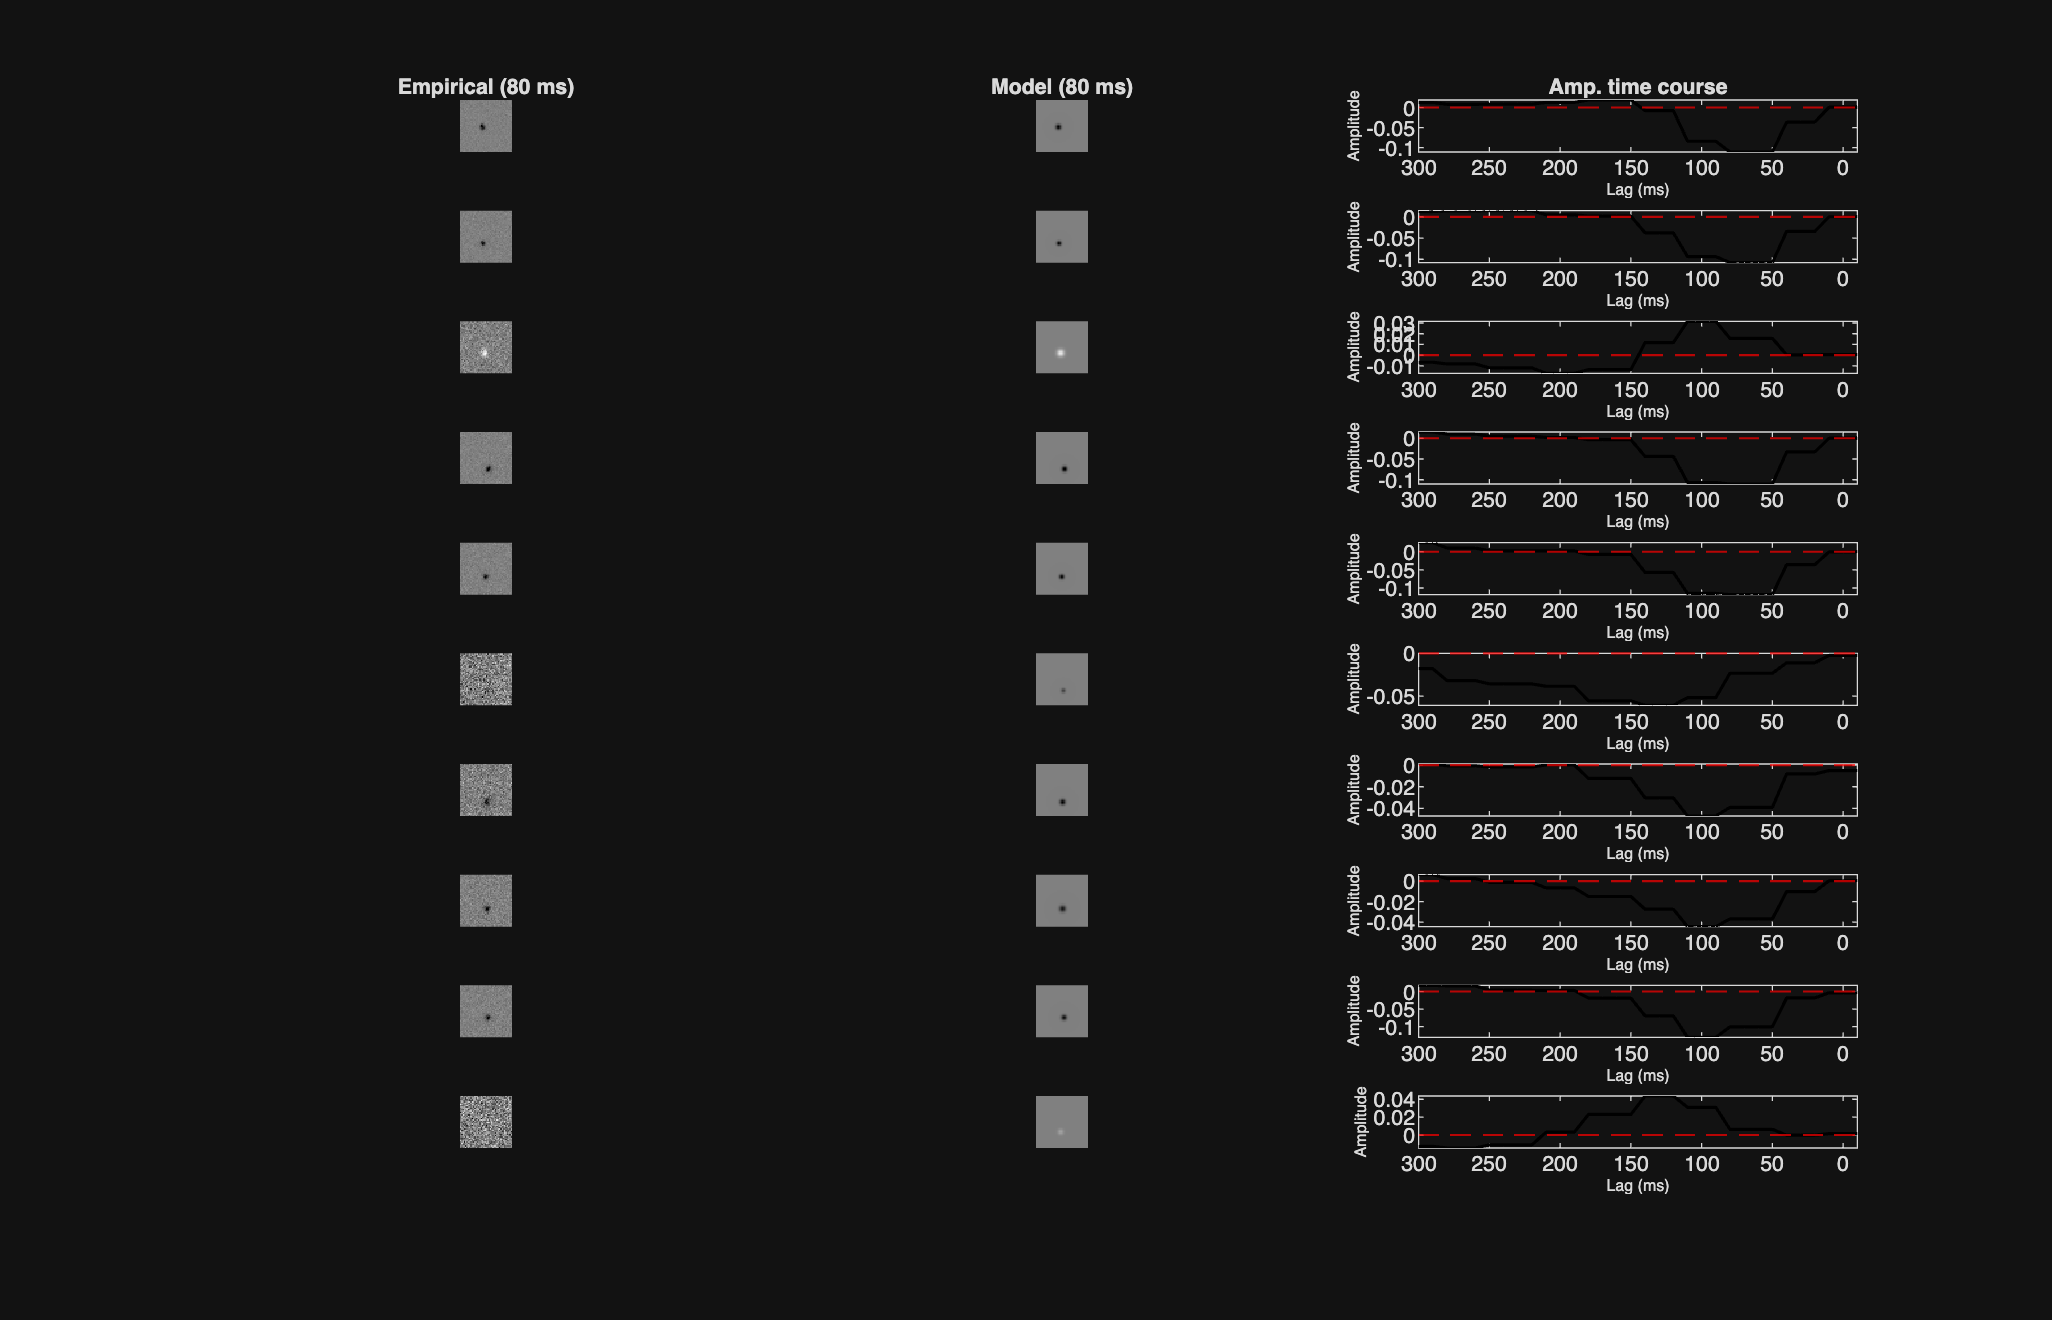

%Part B
figure('Position', [50 50 1400 900]);
for n = 1:length(neurons)
    neuron   = neurons(n);
    strf     = allStrf{n};
    fitted   = allFit{n};
    amps     = allParam(n, 4:end);   

    empFrame    = strf(:,:,lag_idx);
    fitFrame    = fitted(:,:,lag_idx);
    clim_val    = max(abs([empFrame(:); fitFrame(:)]));
    if clim_val == 0, clim_val = 1; end

    subplot(length(neurons), 3, (n-1)*3 + 1);
    imagesc(empFrame, [-clim_val, clim_val]);
    axis image off;
    colormap(gca, 'gray');
    if n == 1, title('Empirical (80 ms)', 'FontSize', 8); end
    ylabel(sprintf('N%d', neuron), 'FontSize', 7);

    subplot(length(neurons), 3, (n-1)*3 + 2);
    imagesc(fitFrame, [-clim_val, clim_val]);
    axis image off;
    colormap(gca, 'gray');
    if n == 1, title('Model (80 ms)', 'FontSize', 8); end

    subplot(length(neurons), 3, (n-1)*3 + 3);
    plot(lag_times, amps, 'k-', 'LineWidth', 1.2);
    xlim([min(lag_times) max(lag_times)]);
    set(gca, 'XDir', 'reverse');   
    yline(0, 'r--', 'LineWidth', 0.8);
    xlabel('Lag (ms)', 'FontSize', 6);
    ylabel('Amplitude', 'FontSize', 6);
    if n == 1, title('Amp. time course', 'FontSize', 8); end
end

The Gaussian does not successfully fit every neuron. In some rows, where the STRF is more noisy, the Gaussian fit more poorly. This tells us that even though the Gaussian is a good approximation for many of these cells in retinaData, depending on the the noise level, the Gaussian might not be able to properly fit and might be fitting to noise, not the actual retina data. 

%Part C
sigma_vals = allParam(:, 3);              
avgWidth = mean(sigma_vals);
peakAmps = zeros(length(neurons), 1);
peakTimes = zeros(length(neurons), 1);
for n = 1:length(neurons)
    amps = allParam(n, 4:end);               
    [~, pkIdx] = max(abs(amps));              
    peakAmps(n) = amps(pkIdx);
    peakTimes(n) = lag_times(pkIdx);         
end

isOFF = peakAmps < 0;
isON  = peakAmps > 0;

pctOFF = 100 * sum(isOFF) / length(neurons);
avgPeakOFF = mean(peakTimes(isOFF));
avgPeakON = mean(peakTimes(isON));

fprintf('Average receptive field width (sigma): %.2f pixels\n', avgWidth);

Average receptive field width (sigma): 1.47 pixels


fprintf('OFF cells: %d / %d  (%.1f%%)\n', sum(isOFF), length(neurons), pctOFF);

OFF cells: 8 / 10  (80.0%)


fprintf('Average time-to-peak – OFF cells: %.1f ms\n', avgPeakOFF);

Average time-to-peak – OFF cells: 81.2 ms


fprintf('Average time-to-peak – ON  cells: %.1f ms\n', avgPeakON);

Average time-to-peak – ON  cells: 120.0 ms
